# 02 Hands On: Continous Problems - Part 2

clear all; close all;

EA = 1000;
f0 = 10;
F = 25;
L = 10;

## Analytic solution

### Deformation plot

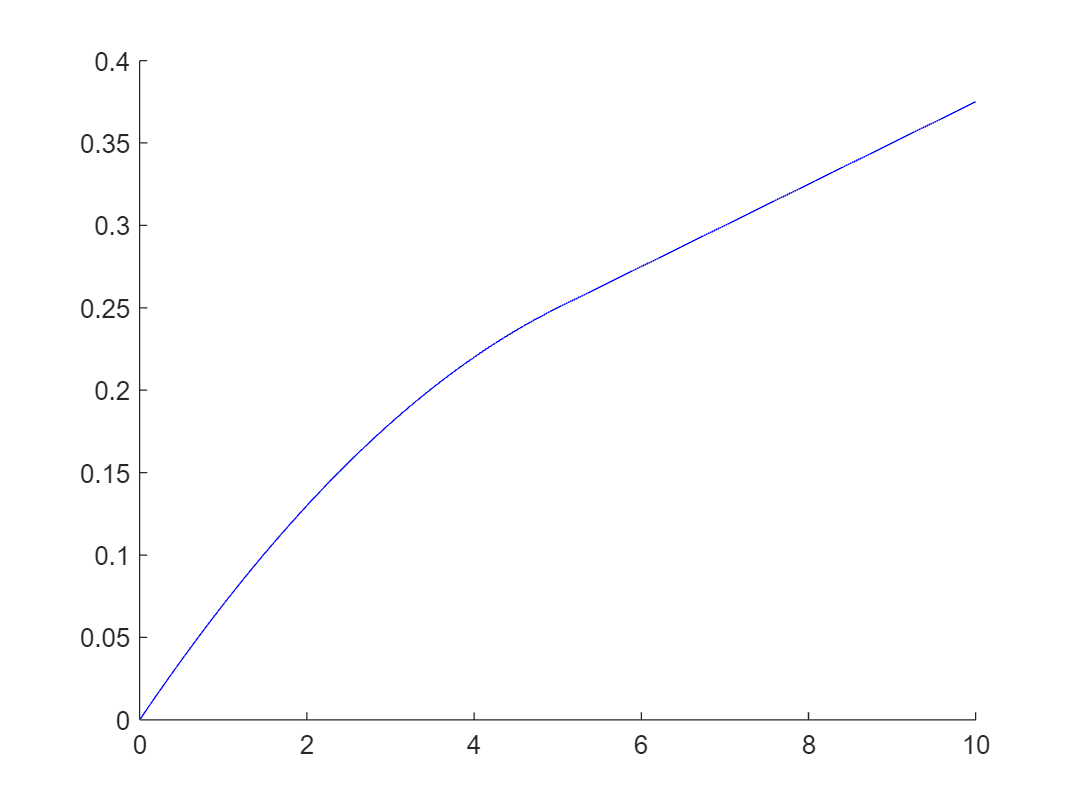

u1 = @(x) (- (f0 / 2) * x .^ 2 + (F + (f0 * (L / 2))) * x) / EA ;
u2 = @(x) (F * x + (f0 / 2) * (L^2 / 4)) / EA;

f1 = figure; hold on;
fplot(u1, [0, L/2], color = 'b');
fplot(u2, [L/2 L], color = 'b');

### Normal force plot

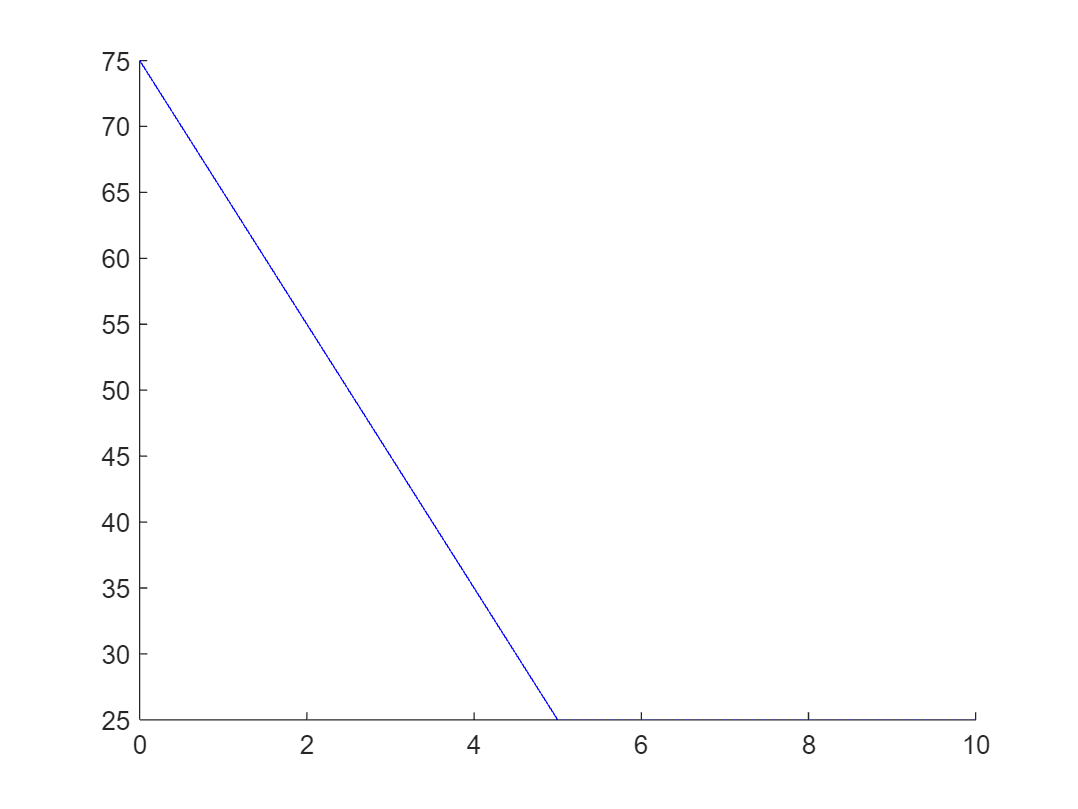

n1 = @(x) (-f0 * x + F + f0 * (L/2));
n2 = F;

f2 = figure; hold on
fplot(n1, [0, L/2], color = 'b');
fplot(n2, [L/2, L], color = 'b');

## Galerkin - linear

a = (F + 1 / 8 * f0 * L) / EA; % derived by hand
uGalerkin = @(x) a * x;

### Displacement plot

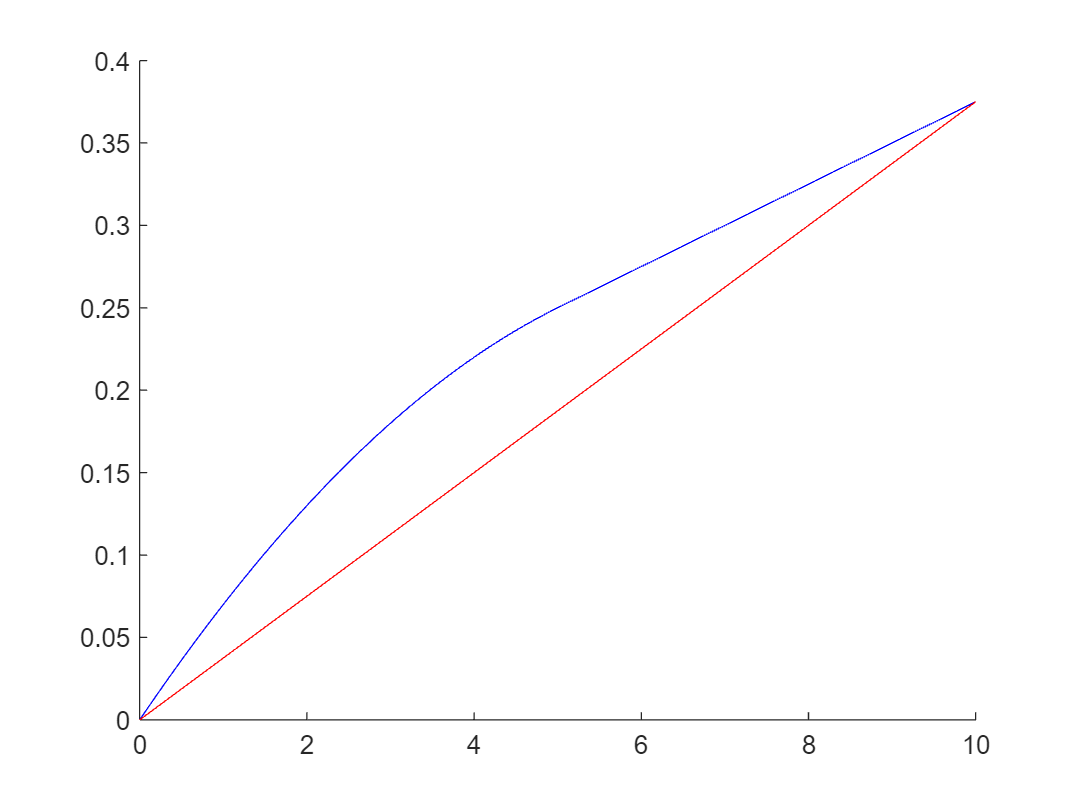

figure(f1);
fplot(uGalerkin, [0 L], color = 'r');

### Normal force plot

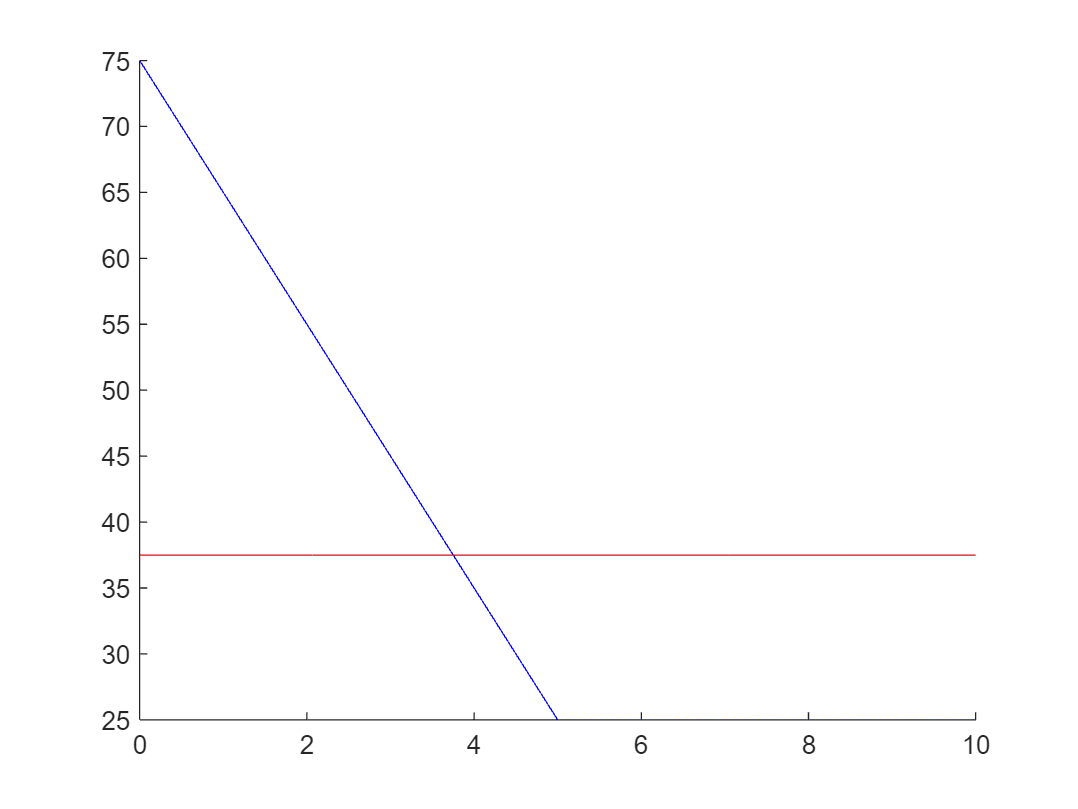

% N(x) = EA*u'
nGalerkin = EA * a;

figure(f2);
fplot(nGalerkin, [0 L], color = 'r');

## Galerkin - quadratic

% leftSide = rightSide
leftSide = EA * [1, L;
                 1, 4/3 * L];
rightSide = [F + 1 / 8 * L * f0;
            F + 1 / 24 * L * f0];

% a1, a2
coefficients = leftSide \ rightSide;
a1 = coefficients(1);
a2 = coefficients(2);

uGalerkinQuad = @(x) a1 * x + a2 * x .^ 2;

### Displacement plot

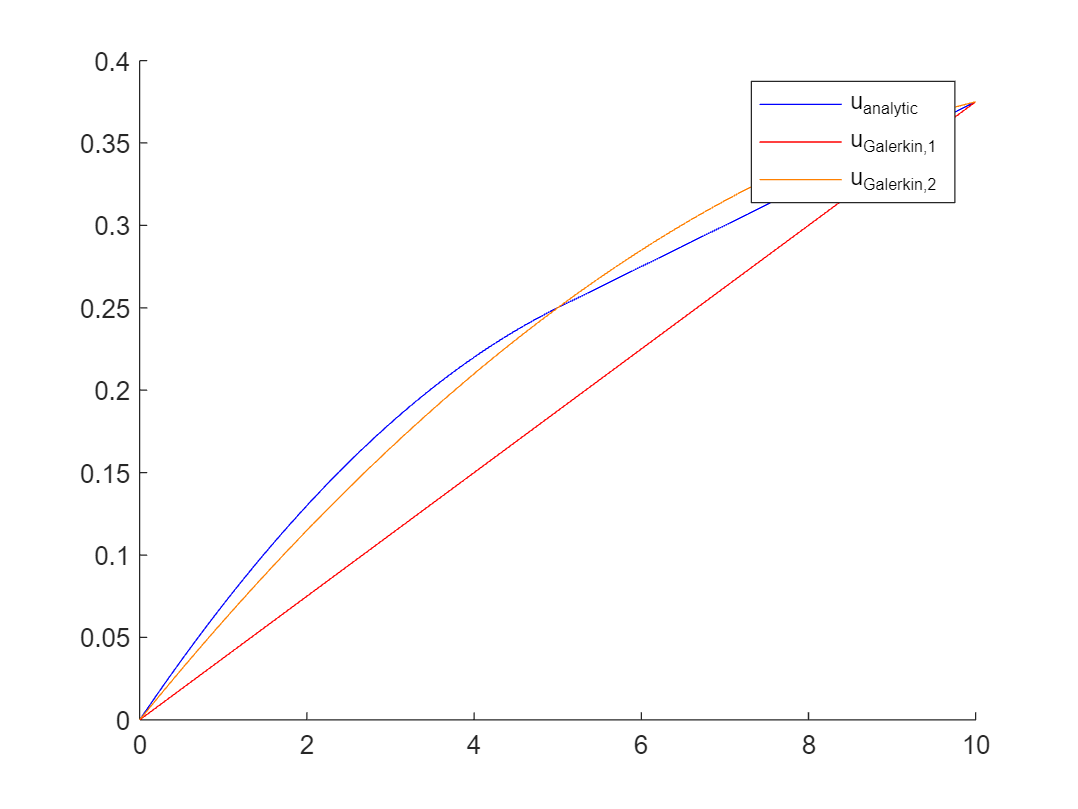

figure(f1);
fplot(uGalerkinQuad, [0 L], color = [1 0.5 0]);
legend({'u_{analytic}', '', 'u_{Galerkin,1}','u_{Galerkin,2}'});

### Normal force plot

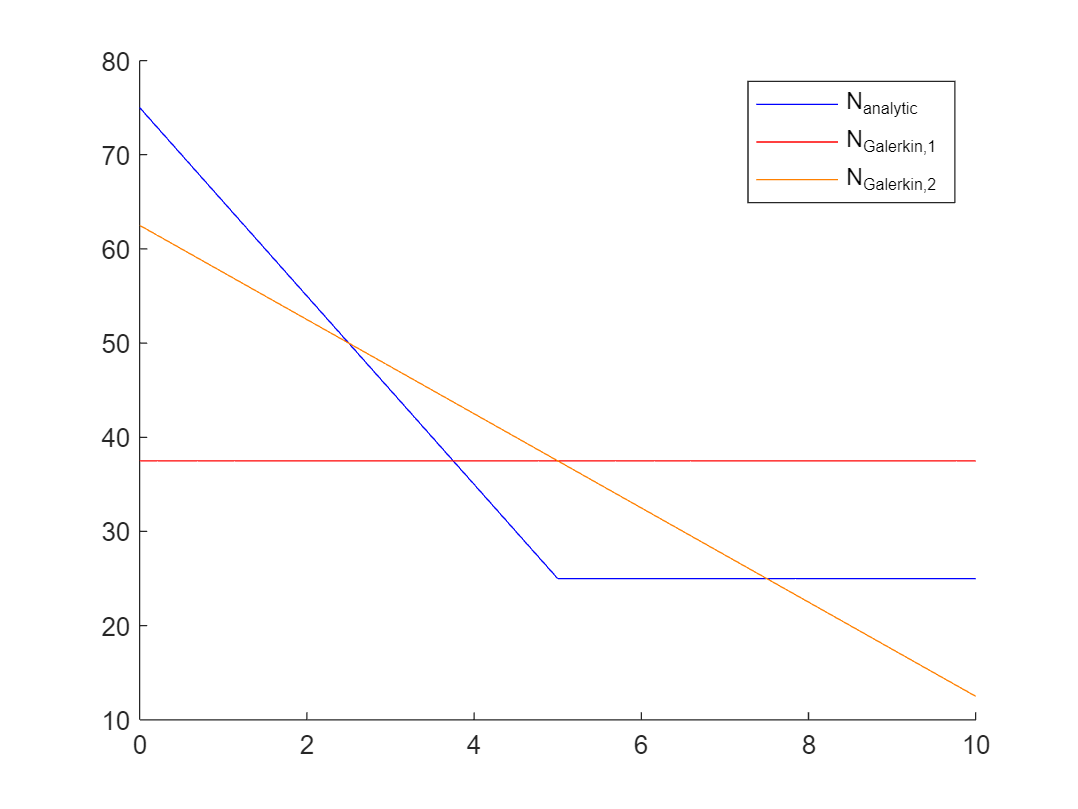

nGalerkinQuad = @(x) EA * (a1 + a2 * 2 * x);

figure(f2);
fplot(nGalerkinQuad, [0 L], color = [1 0.5 0]);
legend({'N_{analytic}', '', 'N_{Galerkin,1}','N_{Galerkin,2}'});

## Galerkin - arbitrary

p = 5;
K = zeros(p);
f = zeros(p, 1);
for j = 1 : p
    for i = j : p
        fhK = @(x) (i * x .^ (i - 1)) .* (j * x .^ (j - 1));
        % Integration
        K(i, j) = EA * integral(fhK, 0, L);
        K(j, i) = K(i, j);
    end % i
    % Force
    fhf = @(x) x .^ j;
    f(j) = F * L ^ j + f0 * integral(fhf, 0, L/2);
end % j
ap = K \ f;

uGalerkinP = @(x) evalPoly(x, ap);

### Displacement plot

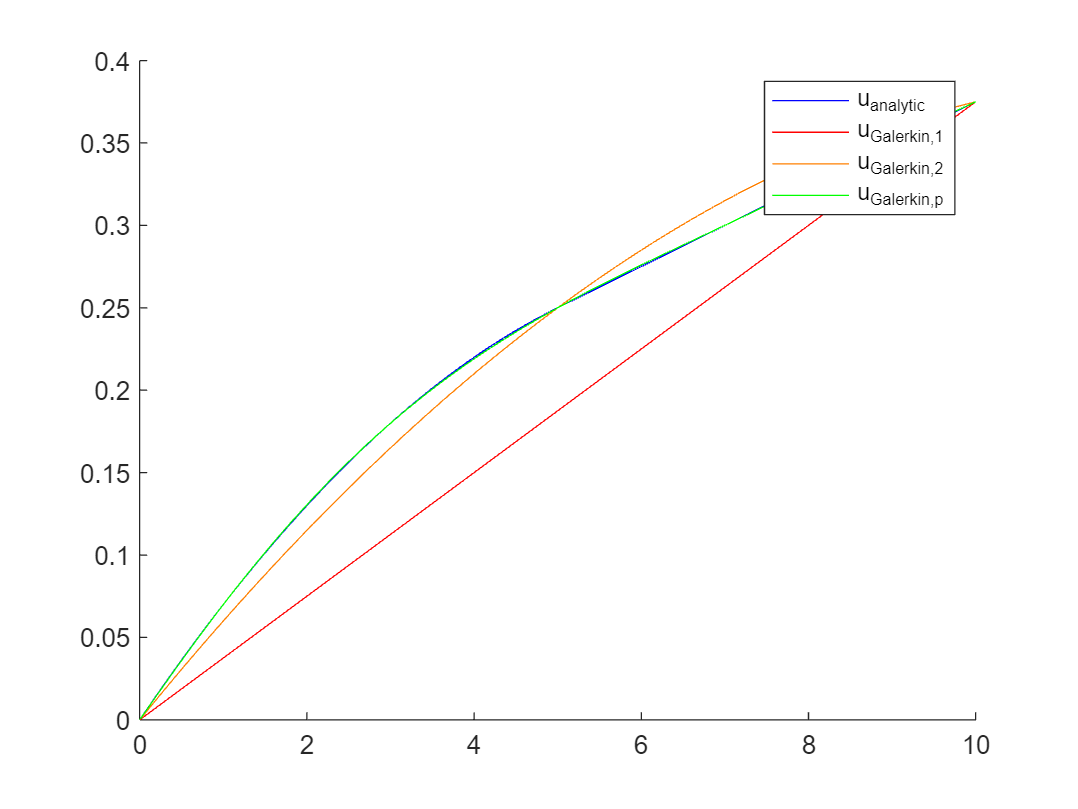

figure(f1);
fplot(uGalerkinP, [0 L], color = 'g');
legend({'u_{analytic}', '', 'u_{Galerkin,1}','u_{Galerkin,2}', 'u_{Galerkin,p}'});

### Normal force plot

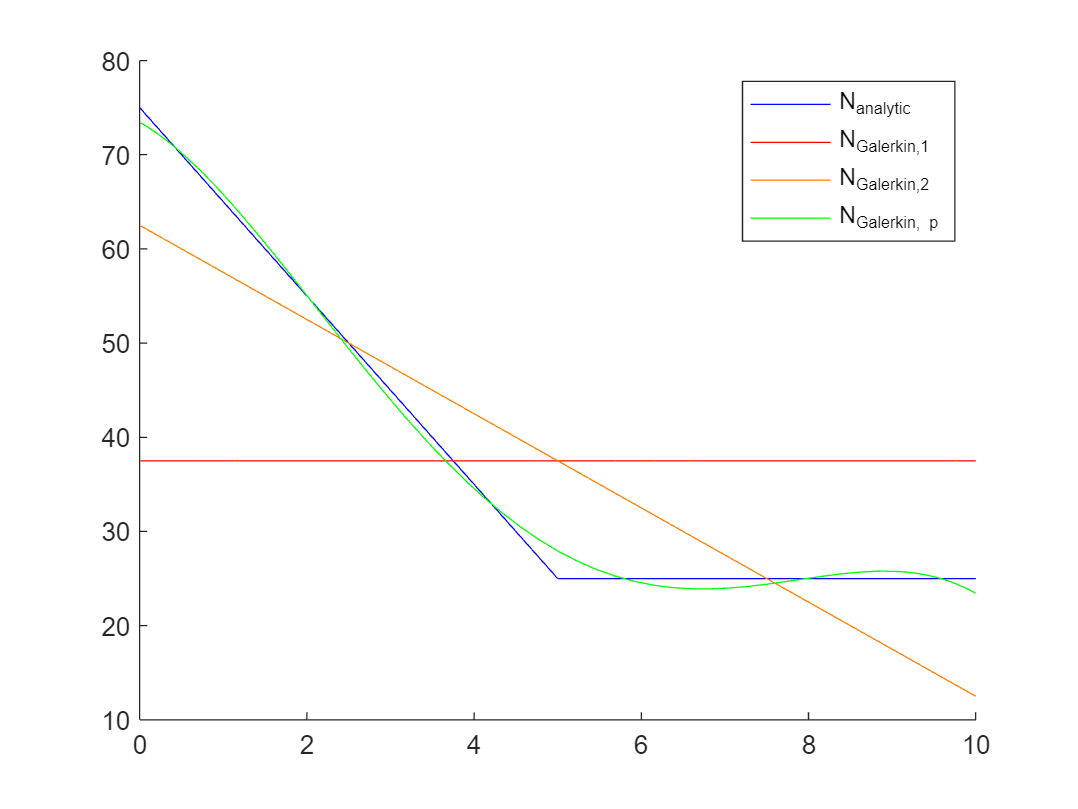

nGalerkinP = @(x) EA * evalPolyDerivative(x, ap);

figure(f2);
fplot(nGalerkinP, [0 L], color = 'g');
legend({'N_{analytic}', '', 'N_{Galerkin,1}','N_{Galerkin,2}','N_{Galerkin, p}'});

## Polynom functions

function p = evalPoly(x, a)
    % Evaluate polynom in the form f(x) = a1 * x^1 + a2 * x^2 + ...
    % INPUT
    %   a (array)     coefficients ai in ascending order 
    p = 0;
    for i = 1 : numel(a)
        p = p + a(i) * x .^ i;
    end
end

function p = evalPolyDerivative(x, a)
    % Evaluate polynom derivative in the form f(x) = a1 + 2 * a2 * x^1 + 3 * a3 * x^2 + ...
    % INPUT
    %   a (array)     coefficients in ascending order 
    p = 0;
    for i = 1 : numel(a)
        p = p + a(i) * i * x .^ (i - 1); 
    end
end